# **Generation of a bilinear quadrilateral mesh**

It returnd a bilinear quadrilateral mesh for a geometry that is identified by a given set of nodes:

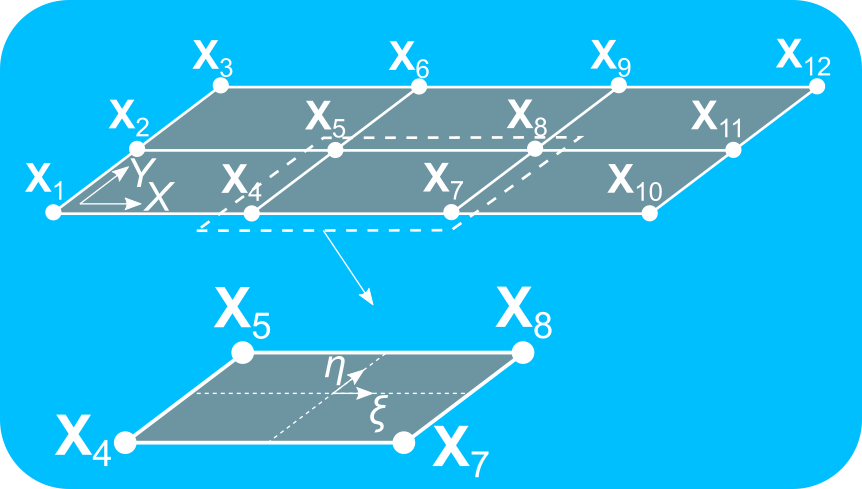

function msh = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesEl)

## **Function Description**

It returns a mesh corresponding to bilinear quadrilateral elements.

**                  Input :**

 `numElx`, `numEly` : Number of elements along the $X$- and the $Y$-directions

                 `numEl` : Total number of elements in the mesh

 `nodesX`, `nodesY` : $X$- and $Y$-Cartesian coordinates of the nodes in the mesh

       `numNodesEl` : Number of nodes per bilinear quadrilateral element

**               Output :**

                    `msh` : Structure containing the nodes and elements of the mesh

                                .`nodes` : Array containing the Cartesian coordinates of the nodes in the mesh

                           .`elements` : Array containing the node IDs per element in the mesh

## **Function Implementation**

### Input validation

arguments
    numElx (1, 1) double {mustBeInteger, mustBePositive}
    numEly (1, 1) double {mustBeInteger, mustBePositive}
    numEl (1, 1) double {mustBeInteger, mustBePositive}
    nodesX (:, :) double
    nodesY (:, 1) double {mustHaveEqualNumberOfElements(nodesX, nodesY)}
    numNodesEl (1, 1) double {mustBeInteger, mustBePositive}
end

### Check input

if numElx*numEly ~= numEl
    error("The provided number of elements do not match")
end

### Assign the nodes of the quadrilateral bilinear mesh

msh.nodes = [nodesX(:) nodesY zeros(numel(nodesY), 1)];
msh.elements = zeros(numEl, numNodesEl);
counterEl = 1;
for ii = 1:numElx
    adv = (ii - 1)*(numEly + 1);
    advplus1 = ii*(numEly + 1);
    for jj = 1:numEly
        msh.elements(counterEl, :) = [jj+adv jj+adv+1 jj+advplus1+1 jj+advplus1];
        counterEl = counterEl + 1;
    end
end

end